**4) Equilibrium State and Output of LTI Systems**

Es.1

syms x_a x_b x_c matA x_t sI_A_INV s t;
matA= sym([0 1 0; -2 -3 1; 0 0 -6]);
x0=[x_a; x_b; x_c];

sI_A_INV=inv(s*eye(size(matA))-matA);

expAt=ilaplace(sI_A_INV);
disp(expAt);

$$\begin{array}{l} \left(\begin{array}{ccc} 2\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t} & {\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t} & \frac{{\mathrm{e}}^{-t}}{5}-\frac{{\mathrm{e}}^{-2\,t}}{4}+\frac{{\mathrm{e}}^{-6\,t}}{20}\\ \sigma_{1}-2\,{\mathrm{e}}^{-t} & \sigma_{1}-{\mathrm{e}}^{-t} & \frac{{\mathrm{e}}^{-2\,t}}{2}-\frac{{\mathrm{e}}^{-t}}{5}-\frac{3\,{\mathrm{e}}^{-6\,t}}{10}\\ 0 & 0 & {\mathrm{e}}^{-6\,t} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\mathrm{e}}^{-2\,t} \end{array}$$


x_t=expAt*x0;
disp(x_t);

$$\begin{array}{l} \left(\begin{array}{c} x_{c}\,\left(\frac{{\mathrm{e}}^{-t}}{5}-\frac{{\mathrm{e}}^{-2\,t}}{4}+\frac{{\mathrm{e}}^{-6\,t}}{20}\right)+x_{b}\,\left({\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t}\right)+x_{a}\,\left(2\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t}\right)\\ -x_{c}\,\left(\frac{{\mathrm{e}}^{-t}}{5}-\frac{{\mathrm{e}}^{-2\,t}}{2}+\frac{3\,{\mathrm{e}}^{-6\,t}}{10}\right)-x_{b}\,\left({\mathrm{e}}^{-t}-\sigma_{1}\right)-x_{a}\,\left(2\,{\mathrm{e}}^{-t}-\sigma_{1}\right)\\ x_{c}\,{\mathrm{e}}^{-6\,t} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\mathrm{e}}^{-2\,t} \end{array}$$

Es.2

syms s t u(t) U(s) sIA_INV X(s) x_t(t);
syms A B;

assume(t>=0);

A = sym([0 1 0; -2 -3 0; 0 1 -6]);
B = sym([0; 4; 0]);
u(t) = 8*[exp((-0.1)*t)*cos(4*t + pi/2)];

U(s) = laplace(u(t), t, s);

sIA_INV = inv(s*eye(size(A)) - A);

X(s) = sIA_INV*B*U(s);

x_t(t) = ilaplace(X(s));
disp(x_t(t));

$$\begin{array}{l} \left(\begin{array}{c} \frac{12800\,{\mathrm{e}}^{-2\,t}}{1961}-\sigma_{1}+\frac{3584000\,{\mathrm{e}}^{-\frac{t}{10}}\,\left(\cos\left(4\,t\right)+\frac{1429\,\sin\left(4\,t\right)}{1120}\right)}{3296441}\\ \sigma_{1}-\frac{25600\,{\mathrm{e}}^{-2\,t}}{1961}+\frac{17932800\,{\mathrm{e}}^{-\frac{t}{10}}\,\left(\cos\left(4\,t\right)-\frac{46229\,\sin\left(4\,t\right)}{56040}\right)}{3296441}\\ \frac{2560\,{\mathrm{e}}^{-t}}{1681}-\frac{6400\,{\mathrm{e}}^{-2\,t}}{1961}+\frac{3840\,{\mathrm{e}}^{-6\,t}}{5081}+\frac{16497664000\,{\mathrm{e}}^{-\frac{t}{10}}\,\left(\cos\left(4\,t\right)-\frac{485911\,\sin\left(4\,t\right)}{5155520}\right)}{16749216721} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{12800\,{\mathrm{e}}^{-t}}{1681} \end{array}$$

Es.3

% Your solution must contain the following parameters
% and also the declaration of the LTI system matrices as symbolic matrices
% -------------------
% You can not modify these lines of code. Simply use them!
%
% ----- system parameters -----
M1 = 1.0; M2 = 2.5;
B = 3.6e-3; B1 = 5.0e-2; B2 = 5.0e-2;
K = 9.1e-2; K1 = 1.0e-1; K2 = 1.0e-1;

% ------ the symbolic matrices -----
syms A_m [4 4] 
syms B_m [4 2] 
syms C_m [2 4]

% your code: 
syms s t;
assume(t>=0);
A_m = sym([0 1 0 0;
    -((K1 + K)/M1) -((B1 + B)/M1) (K/M1) (B/M1);
    0 0 0 1;
    (K/M2) (B/M2) -((K2 + K)/M2) -((B2 + B)/M2)]);
B_m = sym([0 0;
    1/M1 0;
    0 0;
    0 -(1/M2)]);
C_m = sym([1 0 0 0; 0 0 1 0]);

syms x(t) y(t) X(s) Y(s) u(t) U(s);

u(t) = sym([2; -2]);
U(s) = laplace(u(t), t, s);
%disp(U(s));

syms sI_A_INV;
sI_A_INV = inv((s*eye(size(A_m)) - A_m));
%disp(sI_A_INV);

X(s) = sI_A_INV*B_m*U(s);
Y(s) = C_m*sI_A_INV*B_m*U(s);

x(t) = ilaplace(X(s));
y(t) = ilaplace(Y(s));
disp(x(t));

$$\begin{array}{l} \left(\begin{array}{c} 20-\sigma_{5}-187600\,\sigma_{1}-\sigma_{3}-421360\,\sigma_{2}\\ 5720\,\sigma_{2}+\sigma_{4}+250000\,\sigma_{1}\\ 20-\sigma_{5}-187600\,\sigma_{1}-\sigma_{3}-571360\,\sigma_{2}\\ 5720\,\sigma_{2}+\sigma_{4}+100000\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{7}}\,{\sigma_{7}}^{2}}{\sigma_{6}}\\ \sigma_{2}=\sum_{k=1}^{4}\frac{{\mathrm{e}}^{\sigma_{7}\,t}\,\sigma_{7}}{67136\,\sigma_{7}+28140\,{\sigma_{7}}^{2}+500000\,{\sigma_{7}}^{3}+991}\\ \sigma_{3}=2500000\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{7}}\,{\sigma_{7}}^{3}}{\sigma_{6}}\right)\\ \sigma_{4}=28200\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{7}}}{\sigma_{6}}\right)\\ \sigma_{5}=14100\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{7}}}{\sigma_{6}}\right)\\ \sigma_{6}=500000\,{\sigma_{7}}^{3}+28140\,{\sigma_{7}}^{2}+67136\,\sigma_{7}+991\\ \sigma_{7}=\mathrm{root}\left(z^{4}+\frac{469\,z^{3}}{6250}+\frac{4196\,z^{2}}{15625}+\frac{991\,z}{125000}+\frac{141}{12500},z,k\right) \end{array}$$

disp(y(t));

$$\begin{array}{l} \left(\begin{array}{c} 20-14100\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{5}}}{\sigma_{4}}\right)-\sigma_{3}-\sigma_{2}-421360\,\sigma_{1}\\ 20-14100\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{5}}}{\sigma_{4}}\right)-\sigma_{3}-\sigma_{2}-571360\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sum_{k=1}^{4}\frac{{\mathrm{e}}^{\sigma_{5}\,t}\,\sigma_{5}}{67136\,\sigma_{5}+28140\,{\sigma_{5}}^{2}+500000\,{\sigma_{5}}^{3}+991}\\ \sigma_{2}=2500000\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{5}}\,{\sigma_{5}}^{3}}{\sigma_{4}}\right)\\ \sigma_{3}=187600\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{5}}\,{\sigma_{5}}^{2}}{\sigma_{4}}\right)\\ \sigma_{4}=500000\,{\sigma_{5}}^{3}+28140\,{\sigma_{5}}^{2}+67136\,\sigma_{5}+991\\ \sigma_{5}=\mathrm{root}\left(z^{4}+\frac{469\,z^{3}}{6250}+\frac{4196\,z^{2}}{15625}+\frac{991\,z}{125000}+\frac{141}{12500},z,k\right) \end{array}$$

Es.4

% parameters value
R1val = sym(10e3); % Ohm
R2val = sym(25e3); % Ohm
C1val = sym(100e-9); % F
C2val = sym(440e-9); % F
Raval = sym(1e3);  % Ohm
Rbval = sym(20e3);% Ohm

% ----- insert your code below this part -----

syms s t;
syms R1 R2 C1 C2 Ra Rb;

assume(t>=0);
assume(R1>=0);
assume(R2>=0);
assume(C1>=0);
assume(C2>=0);
assume(Ra>=0);
assume(Rb>=0);

R1 = R1val;
R2 = R2val;
C1 = C1val;
C2 = C2val;
Ra = Raval;
Rb = Rbval;

syms x0a;
syms x0b;
x0a = sym([-2.5; 1.7]);
x0b = sym([0; 10]);

syms A;
A = sym([-(1/(R1*C1)+1/(Ra*C1)) 0; -((Rb/Ra)*(1/(R2*C2))) -(1/(R2*C2))]);

syms B;
B = sym([1/(R1*C1); 0]);

syms C;
C = sym([0 1]);

syms u(t);
u(t) = (2+cos(2.5*t)-(1.25*sin(2500*t)));

syms U(s);
U(s) = laplace(u(t), t, s);

syms sI_A_INV [2 2];
sI_A_INV = inv((s*eye(size(A)) - A));

%scenario a
syms Xa(s) Ya(s);
Xa(s) = sI_A_INV*x0a + sI_A_INV*B*U;
Ya(s) = C*sI_A_INV*x0a + C*sI_A_INV*B*U;

syms xa(t);
xa(t) = ilaplace(Xa(s));

syms ya(t);
ya(t) = ilaplace(Ya(s));

%scenario b
syms Xb(s) Yb(s);
Xb(s) = sI_A_INV*x0b + sI_A_INV*B*U(s);
Yb(s) = C*sI_A_INV*x0b+ C*sI_A_INV*B*U(s);

syms xb(t);
xb(t) = ilaplace(Xb(s));

syms yb(t);
yb(t) = ilaplace(Yb(s));


Es.5

% parameters value
R1 = 10e3; R2 = 25e3; C1=100e-9; C2=440e-9; Ra=1e3; Rb=20e3;
x0a = [-2.5; +1.7]; x0b = [0; +10]

x0b =      0
    10



% insert your codee below this line

A = [-(1/(R1*C1)+1/(Ra*C1)) 0; -((Rb/Ra)*(1/(R2*C2))) -(1/(R2*C2))];
B = [1/(R1*C1); 0];
C = [0 1];
D = 0;
sys = ss(A, B, C, D);

x0a = [-2.5; 1.7];
x0b = [0; 10];

t = linspace(0, 10, 50000);

u = (2+cos(2.5*t)-(1.25*sin(2500*t)));
%disp(u);

%scenario a
[y_a, ~, x_a] = lsim(sys, u, t, x0a);
disp(y_a);

    1.7000
    1.9782
    1.9087
    1.8142
    1.7224
    1.6279
    1.5226
    1.4013
    1.2633
    1.1123
    0.9559
    0.8036
    0.6643
    0.5442
    0.4455
    0.3654
    0.2972
    0.2317
    0.1595
    0.0733
   -0.0302
   -0.1499
   -0.2800
   -0.4119
   -0.5361
   -0.6446
   -0.7328
   -0.8007
   -0.8528
   -0.8972
   -0.9436
   -1.0005
   -1.0738
   -1.1648
   -1.2704
   -1.3833
   -1.4941
   -1.5938
   -1.6757
   -1.7369
   -1.7796
   -1.8101
   -1.8372
   -1.8706
   -1.9179
   -1.9830
   -2.0653
   -2.1597
   -2.2577
   -2.3499
   -2.4278
   -2.4864
   -2.5250
   -2.5476
   -2.5619
   -2.5773
   -2.6028
   -2.6447
   -2.7050
   -2.7810
   -2.8660
   -2.9506
   -3.0258
   -3.0842
   -3.1226
   -3.1423
   -3.1493
   -3.1521
   -3.1604
   -3.1822
   -3.2219
   -3.2797
   -3.3508
   -3.4272
   -3.4993
   -3.5586
   -3.5994
   -3.6203
   -3.6248
   -3.6201
   -3.6157
   -3.6207
   -3.6418
   -3.6817
   -3.7381
   -3.8049
   -3.8730
   -3.9331
   -3.9775
   -4.0023
   -4.0083

disp(x_a);

   -2.5000    1.7000
   -0.0669    1.9782
    0.1621    1.9087
    0.1649    1.8142
    0.1660    1.7224
    0.1901    1.6279
    0.2341    1.5226
    0.2875    1.4013
    0.3373    1.2633
    0.3713    1.1123
    0.3812    0.9559
    0.3645    0.8036
    0.3253    0.6643
    0.2733    0.5442
    0.2211    0.4455
    0.1816    0.3654
    0.1644    0.2972
    0.1737    0.2317
    0.2072    0.1595
    0.2568    0.0733
    0.3103   -0.0302
    0.3546   -0.1499
    0.3788   -0.2800
    0.3771   -0.4119
    0.3498   -0.5361
    0.3036   -0.6446
    0.2499   -0.7328
    0.2017   -0.8007
    0.1710   -0.8528
    0.1651   -0.8972
    0.1856   -0.9436
    0.2274   -1.0005
    0.2803   -1.0738
    0.3314   -1.1648
    0.3681   -1.2704
    0.3814   -1.3833
    0.3681   -1.4941
    0.3315   -1.5938
    0.2805   -1.6757
    0.2275   -1.7369
    0.1857   -1.7796
    0.1651   -1.8101
    0.1709   -1.8372
    0.2016   -1.8706
    0.2497   -1.9179
    0.3035   -1.9830
    0.3497   -2.0653
    0.3770   


figure;
subplot(3,1,1);
plot(t, u);
title('Input');
subplot(3,1,2);
plot(t, x_a(:,1), 'b', t, x_a(:,2), 'r');
title('State');
legend('x1', 'x2');
subplot(3,1,3);
plot(t, y_a, 'g');
title('Output');

%scenario b
[y_b, ~, x_b] = lsim(sys, u, t, x0b);
disp(y_b);

   10.0000
    9.7657
    9.5157
    9.2796
    9.0528
    8.8262
    8.5912
    8.3425
    8.0794
    7.8056
    7.5286
    7.2579
    7.0023
    6.7680
    6.5572
    6.3669
    6.1906
    6.0189
    5.8424
    5.6539
    5.4498
    5.2314
    5.0043
    4.7772
    4.5595
    4.3592
    4.1808
    4.0244
    3.8854
    3.7556
    3.6254
    3.4862
    3.3320
    3.1616
    2.9781
    2.7886
    2.6026
    2.4291
    2.2748
    2.1424
    2.0298
    1.9307
    1.8361
    1.7365
    1.6243
    1.4953
    1.3503
    1.1944
    1.0360
    0.8845
    0.7482
    0.6324
    0.5376
    0.4599
    0.3914
    0.3228
    0.2450
    0.1518
    0.0411
   -0.0844
   -0.2179
   -0.3503
   -0.4723
   -0.5767
   -0.6603
   -0.7244
   -0.7749
   -0.8206
   -0.8709
   -0.9339
   -1.0141
   -1.1117
   -1.2218
   -1.3366
   -1.4464
   -1.5427
   -1.6197
   -1.6763
   -1.7158
   -1.7456
   -1.7750
   -1.8132
   -1.8668
   -1.9386
   -2.0265
   -2.1241
   -2.2225
   -2.3123
   -2.3859
   -2.4394
   -2.4736

disp(x_b);

         0   10.0000
    0.2100    9.7657
    0.1928    9.5157
    0.1683    9.2796
    0.1663    9.0528
    0.1901    8.8262
    0.2341    8.5912
    0.2875    8.3425
    0.3373    8.0794
    0.3713    7.8056
    0.3812    7.5286
    0.3645    7.2579
    0.3253    7.0023
    0.2733    6.7680
    0.2211    6.5572
    0.1816    6.3669
    0.1644    6.1906
    0.1737    6.0189
    0.2072    5.8424
    0.2568    5.6539
    0.3103    5.4498
    0.3546    5.2314
    0.3788    5.0043
    0.3771    4.7772
    0.3498    4.5595
    0.3036    4.3592
    0.2499    4.1808
    0.2017    4.0244
    0.1710    3.8854
    0.1651    3.7556
    0.1856    3.6254
    0.2274    3.4862
    0.2803    3.3320
    0.3314    3.1616
    0.3681    2.9781
    0.3814    2.7886
    0.3681    2.6026
    0.3315    2.4291
    0.2805    2.2748
    0.2275    2.1424
    0.1857    2.0298
    0.1651    1.9307
    0.1709    1.8361
    0.2016    1.7365
    0.2497    1.6243
    0.3035    1.4953
    0.3497    1.3503
    0.3770   

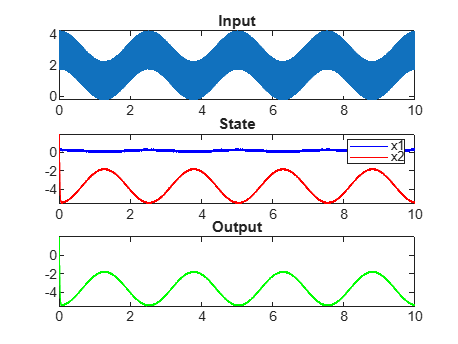


hold off;

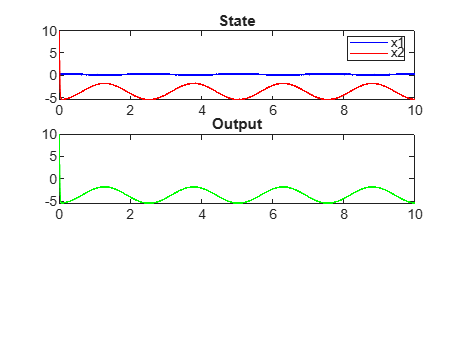

figure;
subplot(3,1,1);
plot(t, x_b(:,1), 'b', t, x_b(:,2), 'r');
title('State');
legend('x1', 'x2');
subplot(3,1,2);
plot(t, y_b, 'g');
title('Output');

Es.6

x0b =      0
    15


   -7.6000
   -7.5321
   -7.4640
   -7.3958
   -7.3275
   -7.2591
   -7.1906
   -7.1219
   -7.0532
   -6.9843
   -6.9153
   -6.8462
   -6.7770
   -6.7077
   -6.6383
   -6.5688
   -6.4992
   -6.4295
   -6.3597
   -6.2897
   -6.2197
   -6.1496
   -6.0794
   -6.0091
   -5.9387
   -5.8682
   -5.7977
   -5.7270
   -5.6563
   -5.5854
   -5.5145
   -5.4435
   -5.3724
   -5.3012
   -5.2300
   -5.1586
   -5.0872
   -5.0157
   -4.9441
   -4.8725
   -4.8008
   -4.7290
   -4.6571
   -4.5852
   -4.5132
   -4.4411
   -4.3689
   -4.2967
   -4.2244
   -4.1521
   -4.0797
   -4.0072
   -3.9346
   -3.8620
   -3.7894
   -3.7166
   -3.6439
   -3.5710
   -3.4981
   -3.4252
   -3.3522
   -3.2791
   -3.2060
   -3.1328
   -3.0596
   -2.9863
   -2.9130
   -2.8396
   -2.7662
   -2.6928
   -2.6192
   -2.5457
   -2.4721
   -2.3984
   -2.3248
   -2.2510
   -2.1773
   -2.1034
   -2.0296
   -1.9557
   -1.8818
   -1.8078
   -1.7338
   -1.6598
   -1.5857
   -1.5116
   -1.4375
   -1.3633
   -1.2891
   -1.2149
   -1.1406

   -2.5000    1.7000
   -2.4446    1.6958
   -2.3894    1.6915
   -2.3342    1.6872
   -2.2791    1.6828
   -2.2240    1.6784
   -2.1691    1.6738
   -2.1142    1.6692
   -2.0595    1.6646
   -2.0048    1.6598
   -1.9502    1.6550
   -1.8957    1.6502
   -1.8412    1.6453
   -1.7869    1.6403
   -1.7326    1.6352
   -1.6784    1.6301
   -1.6243    1.6250
   -1.5703    1.6197
   -1.5163    1.6144
   -1.4625    1.6091
   -1.4087    1.6037
   -1.3550    1.5982
   -1.3014    1.5927
   -1.2479    1.5871
   -1.1945    1.5814
   -1.1411    1.5757
   -1.0878    1.5699
   -1.0346    1.5641
   -0.9815    1.5582
   -0.9285    1.5523
   -0.8756    1.5463
   -0.8227    1.5403
   -0.7699    1.5342
   -0.7172    1.5280
   -0.6646    1.5218
   -0.6121    1.5155
   -0.5596    1.5092
   -0.5073    1.5028
   -0.4550    1.4964
   -0.4028    1.4899
   -0.3507    1.4834
   -0.2986    1.4768
   -0.2467    1.4701
   -0.1948    1.4635
   -0.1430    1.4567
   -0.0913    1.4499
   -0.0396    1.4431
    0.0119   

  -30.0000
  -29.8019
  -29.6042
  -29.4071
  -29.2105
  -29.0144
  -28.8188
  -28.6237
  -28.4291
  -28.2350
  -28.0414
  -27.8483
  -27.6557
  -27.4635
  -27.2719
  -27.0808
  -26.8901
  -26.7000
  -26.5103
  -26.3211
  -26.1324
  -25.9442
  -25.7565
  -25.5692
  -25.3824
  -25.1961
  -25.0103
  -24.8249
  -24.6400
  -24.4556
  -24.2716
  -24.0881
  -23.9051
  -23.7225
  -23.5404
  -23.3588
  -23.1776
  -22.9968
  -22.8166
  -22.6367
  -22.4574
  -22.2784
  -22.1000
  -21.9219
  -21.7444
  -21.5672
  -21.3905
  -21.2143
  -21.0385
  -20.8631
  -20.6882
  -20.5137
  -20.3396
  -20.1660
  -19.9928
  -19.8200
  -19.6477
  -19.4758
  -19.3043
  -19.1332
  -18.9626
  -18.7924
  -18.6226
  -18.4532
  -18.2843
  -18.1157
  -17.9476
  -17.7799
  -17.6126
  -17.4457
  -17.2793
  -17.1132
  -16.9475
  -16.7823
  -16.6174
  -16.4530
  -16.2890
  -16.1253
  -15.9621
  -15.7992
  -15.6368
  -15.4747
  -15.3131
  -15.1518
  -14.9910
  -14.8305
  -14.6704
  -14.5107
  -14.3514
  -14.1924
  -14.0339

         0   10.0000
    0.0544    9.9521
    0.1086    9.9043
    0.1628    9.8566
    0.2169    9.8091
    0.2710    9.7618
    0.3249    9.7146
    0.3788    9.6675
    0.4325    9.6205
    0.4862    9.5737
    0.5398    9.5271
    0.5934    9.4805
    0.6468    9.4342
    0.7002    9.3879
    0.7534    9.3418
    0.8066    9.2958
    0.8597    9.2500
    0.9128    9.2043
    0.9657    9.1587
    1.0186    9.1132
    1.0714    9.0679
    1.1241    9.0228
    1.1767    8.9777
    1.2292    8.9328
    1.2816    8.8880
    1.3340    8.8434
    1.3863    8.7989
    1.4385    8.7545
    1.4906    8.7102
    1.5427    8.6661
    1.5946    8.6221
    1.6465    8.5782
    1.6983    8.5345
    1.7500    8.4908
    1.8016    8.4473
    1.8532    8.4040
    1.9046    8.3607
    1.9560    8.3176
    2.0073    8.2746
    2.0585    8.2318
    2.1097    8.1890
    2.1607    8.1464
    2.2117    8.1039
    2.2626    8.0615
    2.3134    8.0193
    2.3641    7.9771
    2.4148    7.9351
    2.4654   

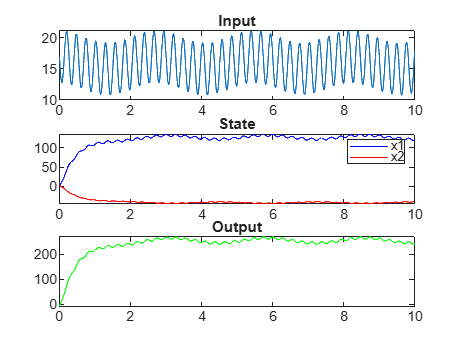

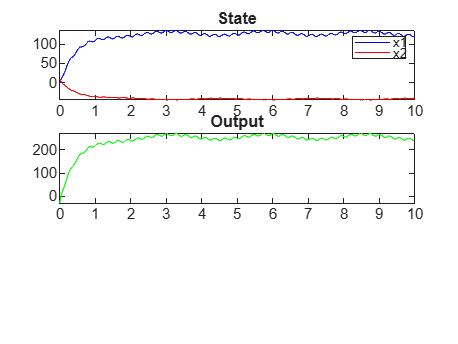

% primo punto : creo le matrici numeriche 
A=[-2,0 

    -8,-24]
B=[16;0]
C=[1,-3]
D=0
% secondo punto:creo due array per gli stati iniziali xOa e x0b
x0a=[-4;8]
x0b=[0;15]
% creo un array nell'intervallo di tempo [0,10] con 5000 istanti di tempo
t = linspace(0, 10, 50000)
u=[16+cos(2.3*t)-4.2*sin(23*t)] 

% SCENARIO A
SYS=ss(A,B,C,D)
[y_a, t_out, x_a] = lsim(SYS, u, t, x0a) 

% SCENARIO B
SYS=ss(A,B,C,D)
[y_b, t_out, x_b] = lsim(SYS, u, t, x0b)


Es.7

%P1
% let's declare the complex symbolic variable "s" and the real parameter p1
syms s
syms p1 real 
A = [0, -4
     1, p1] 
pA = poly2sym(charpoly(A),s) % polinomio caratteristico della matrice A 

%forziamo ora un autovalore immaginario p1=0
PO_p1 = 0 

%ora troviamo gli effettivi autovalori, mettiamo it valore p1=0 in p1 nel polinomio caratteristico
pA0 = subs(pA, p1, PO_p1) 

PO_eig = solve(pA0) 

%trovo ora it periodo dell'oscillazione
PO_time_period = (2*pi)/imag(PO_eig(2))
PO_T = double(PO_time_period) 
%P2
p3 = sym(0)
syms p2
B = [p2; p3]
C = sym([0 1]) 

sI_A = s*eye(size(A))-A
sI_Ainv = inv(sI_A)
Gs = C*sI_Ainv*B

assume(p1<0)

gainG = subs(Gs,s,0)

Yinfty = sym(100)
U = sym(1)
eq_p2 = gainG*U==Yinfty
p2_sol = solve(eq_p2, p2)
RO_p2 = double(p2_sol)

syms xi
assume(xi<=1)
assumeAlso(xi>=0)
assumptions(xi) 

xi_eq = (pi*xi)^2==(log(0.25))^2*(1-xi^2); % <<-- the assigned max overshoot
xi_sol = vpa(solve(xi_eq, xi),6)% <<-- the corresponding damping factor 

RO_p1 = -4*double(xi_sol) 

%P3
ST_T = 9.2/(-RO_p1)
% the matrices A, B, C and D as numerical matrices
matA = double(subs(A, p1, RO_p1))
matB = double(subs(B, [p2, p3], [RO_p2, 0]))
matC = double(C)
matD = zeros(1)

LTIsys = ss(matA, matB, matC, matD) 

% we request the evaluation of the settling time with 0.01 as threshold
StepOutputInfo = stepinfo(LTIsys,"SettlingTimeThreshold", 0.01)
% the settling time is
ST_SI_T = StepOutputInfo.SettlingTime


Es.8

syms x_a x_b x_c
syms s t
syms matA
A=[0,-2,0
-2,-3,1
0,0,-5]
matA=sym(A)
 
x0=[x_a
    x_b
    x_c]

expAt=expm(matA*t)
x_t=expAt*x0
% per verificare che in x_t ci siano determinati valori vado ad usare questo
% comando
check=contains(char(x_t), {'exp(t)', 'exp(-4*t)', 'exp(-5*t)'})
% il comando char mi converte x_t in una stringa
% contains verifica che siano contenuti nella stringa quei determinati
% valori che elenco

% faccio andare il codice e vedo che non genera errore quindi ho tutti quei
% tre termini in x_t
x0_1=[x_a
    (5/2)*x_a
    -3*x_a]
x_b=(5/2)*x_a
x_c=(-3)*x_a
 
xNEW_t=expAt*x0_1

check=isequal(xNEW_t,exp(-5*t))


Es.9

k=10 
J=0.01 
c=0.004 
Kt=0.05

A=[0,1
    -k/J, -c/J]

B=[0
    Kt/J]

C=[1,0]

D=[0]

lambdaC=eig(A)

x0=[2
    -40]

deltat=5.0*1e-4
t = 0.0:deltat:10.0 % t = t_iniziale:passo:t_finale

t0 = 0

A_exp = expm(A * deltat)

% Ingresso nullo
u = zeros(size(t))

% Definizione del sistema continuo
sys = ss(A, B, C, D)

% Simulazione del sistema con ingresso nullo e stato iniziale x0
[freeY, ~, freeX] = lsim(sys, u, t, x0) % lsim simula la risposta di un sistema dinamico continuo o discreto a un dato ingresso,
% anche con condizioni iniziali non nulle. 

% ingresso gradino unitario
u = ones(size(t)) % crea un vettore lungo quanto it tempo t in cui ogni valore vale 1 

% Stato iniziale nullo
x0 = [0; 0]

% Definizione del sistema continuo
sys = ss(A, B, C, D)

% simulazione della risposta al gradino
[stepY, ~, stepX] = lsim(sys, u, t, x0) % nella tilde dovrebbe esserci tout = vettore tempo restituito (di solito uguale a t)
% ma ora non ci interessa auindi mettiamo tilde.


Es.10

% the complex frequency variable "s"
syms s
%
% insert your code

A = sym([-1 -2 -2;
         -2 -3 4;
         1 -1 -2]);
B = sym([6; 
         8;
         1]);
C = sym([0 2 1]);
D = sym([0]); 

eigA = sort(eig(A))

G_s(s) = simplify(C*inv(s*eye(length(A))-A)*B+D);

[numG, denG] = numden(G_s(s)); % numden function extracts numerator and denominator

mu_G = subs(G_s(s), s, 0); % static gain G(0)
zeros_SET = sort(solve(numG == 0, s, 'MaxDegree', 3)); % sorted zeros

poles_SET = sort(poles(G_s(s))) % sorted poles

LogicalFLAGS = ismember(eigA,poles_SET) %use the function ismember() and compare the contents of eigA (as first array) with poles_SET (as second array).
